# Full Injector Simulation

## Flow Characteristics

If using film cooling, set the film cooling percentage equal to the percent of film cooling in total mass flow.

clear;

mToFt = double(unitConversionFactor('m','ft')); 

chamberPressure = 30*10^5; %         Pa         Chamber pressure

ox.mDot = 1.40346; %                      kg/s          Fuel mass flow rate 
fu.mDot = 0.46782; %                      kg/s          Oxidizer mass flow rate
% filmCoolingPercent = 0; %           %             Percentage of total mass flow in film cooling

% co.mDot = filmCoolingPercent*(ox.mDot + fu.mDot);
% fu.mDot = fu.mDot - co.mDot;

ox.N_orifices = 20; %                 -          Number of oxidizer orifices
fu.N_orifices = 20; %                 -          Number of fuel orifices
% co.N_orifices = 0; %                 -          Number of film cooling holes

ox.rho = 798; %                       kg/m^3     Oxidizer density
fu.rho = 789; %                       kg/m^3     Fuel density
% co.rho = 0; %                       kg/m^3     Coolant density

ox.C_d = 0.65; %                       -          Oxidizer discharge coefficient
fu.C_d = 0.65; %                       -          Fuel discharge coefficient
% co.C_d = 0; %                       -          Coolant discharge coefficient

ox.deltaP = 18.2*10^5; %                bar       Oxidizer pressure difference
fu.deltaP = 16.8*10^5; %                bar       Fuel pressure difference
% co.deltaP = 0*10^5; %                bar       Coolant pressure difference

ox.stiffness = ox.deltaP/chamberPressure;
fu.stiffness = fu.deltaP/chamberPressure;

ox.flow = getFlow(ox); % Gets flow data for oxidizer
fu.flow = getFlow(fu); % Gets flow data for fuel
% if filmCoolingPercent ~= 0
%     co.flow = getFlow(co); % Gets flow data for coolant
% end

centralMixtureRatio = ox.mDot/fu.mDot;
% totalMixtureRatio   = ox.mDot/(fu.mDot + co.mDot);

fDisp('Oxidizer Passage Diameter', ["in", "mm"], ox.flow.d.*[100/2.54, 1000]);

Oxidizer Passage Diameter 	0.06287 in 	[1.597 mm]


fDisp('Oxidizer Total Area    ', ["in^2", "mm^2"], ox.flow.A.*ox.N_orifices*[(100/2.54)^2, 10^6]);

Oxidizer Total Area     	0.0621 in^2 	[40.06 mm^2]


% fDisp('Oxidizer Volume Flow Rate', ["ft^3/s", "m^3/s"], ox.flow.Q.*[mToFt^3,1]);
fDisp('Oxidizer Exit Velocity   ', ["ft/s", "m/s"], ox.flow.v.*[mToFt, 1]);

Oxidizer Exit Velocity    	144   ft/s 	[43.9  m/s]


fDisp('Oxidizer Stiffness       ', "%", ox.stiffness*100);

Oxidizer Stiffness        	60.67 % 



fDisp('Fuel Passage Diameter    ', ["in", "mm"], fu.flow.d.*[100/2.54, 1000]);

Fuel Passage Diameter     	0.03714 in 	[0.9433 mm]


fDisp('Fuel Total Area        ', ["in^2", "mm^2"], fu.flow.A.*fu.N_orifices.*[(100/2.54)^2, 10^6]);

Fuel Total Area         	0.02167 in^2 	[13.98 mm^2]


% fDisp('Fuel Volume Flow Rate    ', ["ft^3/s", "m^3/s"], fu.flow.Q.*[mToFt^3,1]);
fDisp('Fuel Exit Velocity       ', ["ft/s", "m/s"], fu.flow.v.*[mToFt, 1]);

Fuel Exit Velocity        	139.2 ft/s 	[42.42 m/s]


fDisp('Fuel Stiffness           ', "%", fu.stiffness*100);

Fuel Stiffness            	56    % 



% if filmCoolingPercent~= 0
%     fDisp('Coolant Passage Diameter', ["in", "mm"], co.flow.d.*[100/2.54, 1000]);
%     fDisp('Coolant Total Area    ', ["in^2", "mm^2"], co.flow.A.*co.N_orifices.*[(100/2.54)^2, 10^6]);
%     fDisp('Coolant Volume Flow Rate', ["ft^3/s", "m^3/s"], co.flow.Q*[mToFt^3,1]);
%     fDisp('Coolant Exit Velocity   ', ["ft/s", "m/s"], co.flow.v.*[mToFt, 1]);
% 
%     fDisp('Central Mixture Ratio   ', "-", centralMixtureRatio);
% end

fDisp('Orifice Diameter Ratio  ', "", ox.flow.d/fu.flow.d);

Orifice Diameter Ratio   	1.693  


% fDisp('Total Mixture Ratio     ', "", totalMixtureRatio);

## Optimum Diameter Ratio

The NASA injector document provides a correlation for optimum mixing on page 18 which is as follows:

This is implemented in the code below and output for the case that the user inputs.

This formula has only been verified for diameter ratios of up to 1.5. In general, the diameter ratio should be close to 1.22.

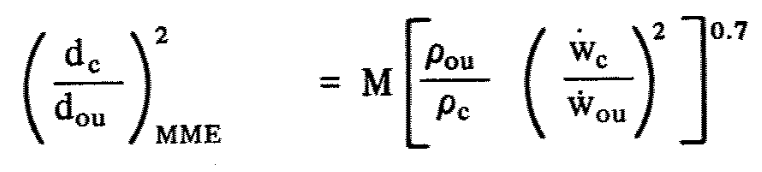

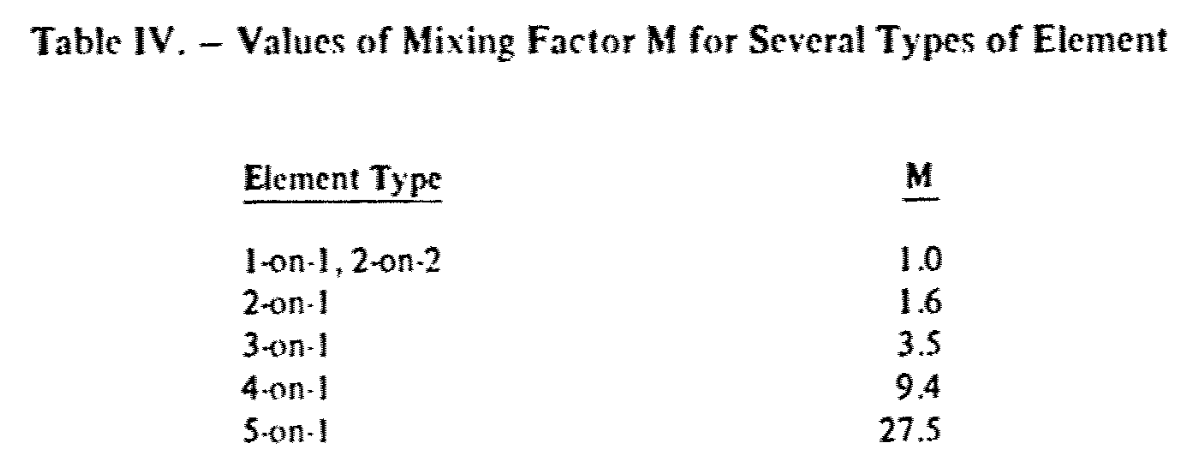

M = 1;

optDiameterRatio = sqrt(M*((fu.rho/ox.rho)*(ox.mDot/fu.mDot)^2)^0.7);

fDisp('Optimum Diameter Ratio', "", optDiameterRatio);

Optimum Diameter Ratio 	2.149  


## Impingement Angle

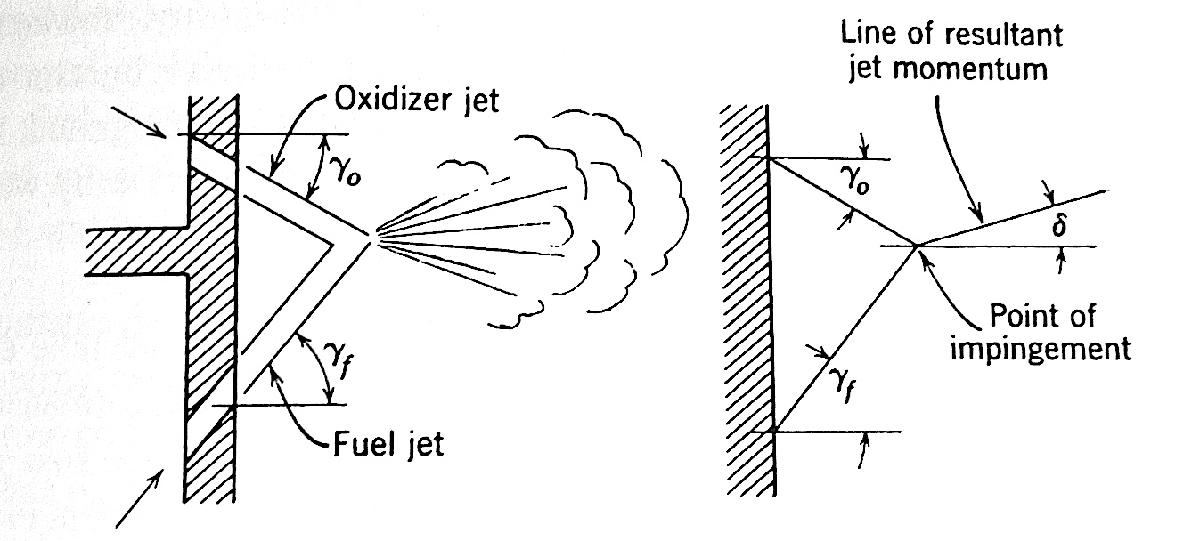

ox.gamma = 10;
fu.gamma = 50;

alpha = ox.gamma + fu.gamma; % Convergence angle

tand = (ox.mDot*ox.flow.v*sind(ox.gamma) - fu.mDot*fu.flow.v*sind(fu.gamma))...
    / (ox.mDot*ox.flow.v*cosd(ox.gamma) + fu.mDot*fu.flow.v*cosd(fu.gamma));
delta = atand(tand);

gamma_f = asind(ox.mDot*ox.flow.v*sind(ox.gamma)/(fu.mDot*fu.flow.v));

fDisp('Resultant Angle (delta)   ', 'deg', delta);

Resultant Angle (delta)    	-3.509 deg 


fDisp('Impingement angle (alpha) ', 'deg', alpha);

Impingement angle (alpha)  	60    deg 


fDisp('Fuel Angle for Axial Flow ', 'deg', gamma_f);

Fuel Angle for Axial Flow  	32.63 deg 
